clear; close all; clc;

%% === General Data ===
% Physical constants
m0 = 28801;             % Initial mass (kg)
g0 = 9.80665;           % Gravity (m/s^2)
Isp = 311;              % Specific impulse (s)
days = 86400.002;       % Seconds per day

% Earth & Moon parameters
Re = 6378.137;          % Earth radius (km)
Rm = 1737.1;            % Moon radius (km)
m_e = 5.972168e24;      % Earth mass (kg)
m_m = 7.346e22;         % Moon mass (kg)
mu_e = 398600.4418;     % Earth gravitational parameter (km^3/s^2)
mu_m = 4902.800118;     % Moon gravitational parameter (km^3/s^2)
D = 384784;             % Earth-Moon distance (km)
    RS = D*(m_m/m_e)^(2/5); % Sphere of influence (km)

% Initial orbit parameters
alpha0 = 90;            % Right Ascension (deg)
dec0 = 15;              % Declination (deg)
gamma0 = 40;            % Flight path angle (deg)
alt0 = 320;             % Altitude (km)

% Mission time parameters
fac = 0.9924;           % Fraction of escape velocity for TLI
ttt = 3 * days;         % Time of flight to perilune (s)
tf = ttt + 2.667*days;  % Final integration time (s)

%% === Initial Conditions ===
z0 = Re + alt0;                     % Orbital radius (km)
speed_at_LEO = sqrt(mu_e / z0);     % Circular velocity at LEO (km/s)
vesc = sqrt(2 * mu_e / z0);         % Escape velocity at LEO (km/s)
speed_TLI = fac * vesc;             % Trans Lunar Injection speed (km/s)
delta_v = speed_TLI - speed_at_LEO; % ΔV required (km/s)

% Compute initial fuel usage
fuel_before_optimization = compute_fuel_used(delta_v, Isp, g0, m0);
efficiency = (fuel_before_optimization / m0) * 100;

% Output: Pre-optimization results
fprintf('\n=== Before Optimization ===\n');


=== Before Optimization ===


fprintf('fac (nominal)         = %.5f\n', fac);

fac (nominal)         = 0.99240


fprintf('ΔV used (km/s)        = %.4f\n', delta_v);

ΔV used (km/s)        = 3.1124


fprintf('Fuel used (kg)        = %.4f\n', fuel_before_optimization);

Fuel used (kg)        = 18420.8002


fprintf('Efficiency (%%)        = %.2f %%\n', efficiency);

Efficiency (%)        = 63.96 %



%% === Optimization of fac ===
fac_min = 0.97;
fac_max = 1.01;
objective = @(fac) fuel_used_fac(fac, alt0, mu_e, vesc, Re, Isp, m0, g0);
[fac_opt, min_fuel_used] = fminbnd(objective, fac_min, fac_max);

[deltaV_opt, ~] = compute_total_deltavandfuel(alt0, mu_e, fac_opt, vesc, Re, Isp, m0, g0);
opt_efficiency = (min_fuel_used / m0) * 100;

% Output: Optimization results
fprintf('\n=== Optimization Results ===\n');


=== Optimization Results ===


fprintf('Optimal fac           = %.5f\n', fac_opt);

Optimal fac           = 0.97004


fprintf('ΔV (km/s)             = %.4f\n', deltaV_opt);

ΔV (km/s)             = 2.8685


fprintf('Fuel used (kg)        = %.4f\n', min_fuel_used);

Fuel used (kg)        = 17556.5930


fprintf('Efficiency (%%)        = %.2f %%\n', opt_efficiency);

Efficiency (%)        = 60.96 %


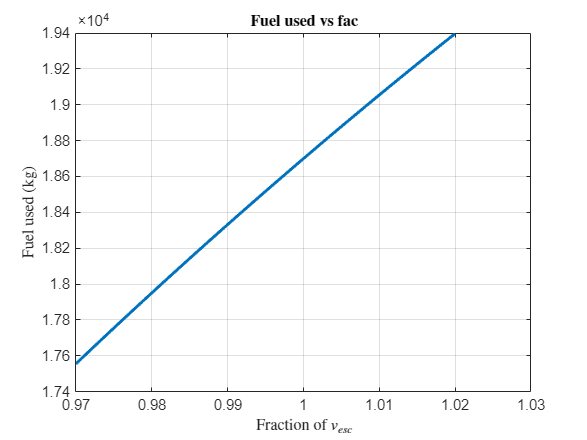


% Plot: Fuel vs fac
fac_vals = linspace(0.97, 1.02, 200);
fuel_vals = arrayfun(@(f) compute_fuel_used(f*vesc - speed_at_LEO, Isp, g0, m0), fac_vals);

figure;
plot(fac_vals, fuel_vals, 'LineWidth', 2);
xlabel('Fraction of $v_{esc}$', 'Interpreter', 'latex');
ylabel('Fuel used (kg)', 'Interpreter', 'latex');
title('\bf{Fuel used vs fac}', 'Interpreter', 'latex');
grid on;

%% === Date and State of Moon at Arrival ===
year = 2020; 
month = 5; 
day = 4; 
hour = 12; 
minute = 0; 
second = 0;
UT = 12; % Universal Time (hours)
t0 = 0;

jd0 = julian_day(year, month, day, UT);
[rm0, vm0] = simpsons_lunar_ephemeris(jd0);
[RA, Dec] = ra_and_dec_from_r(rm0);

distance = norm(rm0);
hmoon = cross(rm0, vm0);
inclmoon = acosd(hmoon(3) / norm(hmoon));
ym0 = [rm0(1), rm0(2), rm0(3), vm0(1), vm0(2), vm0(3)]; % State vector

% Output: Moon State Vector ===
fprintf('\n=== Date and Time of Arrival at Moon ===\n');


=== Date and Time of Arrival at Moon ===


fprintf('Date             = %02d/%02d/%04d %02d:%02d:%02d\n', month, day, year, hour, minute, second);

Date             = 05/04/2020 12:00:00


fprintf('Distance         = %.3f km\n', distance);

Distance         = 360784.564 km


fprintf('RA               = %.3f°\n', RA);

RA               = 185.107°


fprintf('Dec              = %.3f°\n', Dec);

Dec              = 2.917°


fprintf('Moon Inclination = %.3f°\n', inclmoon);

Moon Inclination = 23.676°


fprintf('Position Vector  = [%.2f, %.2f, %.2f] km\n', rm0(1), rm0(2), rm0(3));

Position Vector  = [-358886.92, -32072.31, 18358.92] km


fprintf('Velocity Vector  = [%.4f, %.4f, %.4f] km/s\n', vm0(1), vm0(2), vm0(3));

Velocity Vector  = [0.0920, -0.9833, -0.4303] km/s



%% === Initial Probe Position and Velocity Vector ===
I = [1; 0; 0]; 
J = [0; 1; 0]; 
K = cross(I, J);
[r0, v0, y0, w0_hat] = launch_conditions2rv(Re, dec0, alt0, alpha0, gamma0, speed_TLI, rm0);

% Output: Probe's departure conditions
fprintf('\n=== The Probe at Earth Departure (t = %g s) ===\n', t0);


=== The Probe at Earth Departure (t = 0 s) ===


fprintf('Altitude                        = %.1f km\n', alt0);

Altitude                        = 320.0 km


fprintf('Right Ascension                 = %.1f°\n', alpha0);

Right Ascension                 = 90.0°


fprintf('Declination                     = %.1f°\n', dec0);

Declination                     = 15.0°


fprintf('Flight Path Angle               = %.1f°\n', gamma0);

Flight Path Angle               = 40.0°


fprintf('Speed (TLI)                     = %.4f km/s\n', speed_TLI);

Speed (TLI)                     = 10.8266 km/s


fprintf('Escape Speed                    = %.4f km/s\n', vesc);

Escape Speed                    = 10.9096 km/s


fprintf('v / v_esc                       = %.5f\n', speed_TLI / vesc);

v / v_esc                       = 0.99240


fprintf('Inclination of Translunar Orbit = %.3f°\n', acosd(w0_hat(3)));

Inclination of Translunar Orbit = 15.551°


%% === Numerical Integration ===
options = odeset('RelTol', 1.e-10, 'AbsTol', 1.e-10, 'Stats', 'off');
rates_func = @(t, y) rates(t, y, jd0, ttt, days, mu_m, mu_e);
[t, y] = ode113(rates_func, [t0 tf], y0, options);

% Extract spacecraft trajectory in ECI frame
X = y(:,1);  % X-position (km)
Y = y(:,2);  % Y-position (km)
Z = y(:,3);  % Z-position (km)
vX = y(:,4); % X-velocity (km/s)
vY = y(:,5); % Y-velocity (km/s)
vZ = y(:,6); % Z-velocity (km/s)

%% === Spacecraft and Moon Trajectory Analysis ===
% Initialize and preallocate compulsory variables
N        = length(t);   % Total number of time steps
x        = zeros(N, 1); % Probe position in X axis in Moon-fixed frame
y        = zeros(N, 1); % Probe position in Y axis in Moon-fixed frame
z        = zeros(N, 1); % Probe position in ZS axis in Moon-fixed frame
Xm       = zeros(N, 1); % Moon position in X axis in ECI frame
Ym       = zeros(N, 1); % Moon position in Y axis in ECI frame
Zm       = zeros(N, 1); % Moon position in Z axis in ECI frame
vXm      = zeros(N, 1); % Moon velocity in X axis in ECI frame
vYm      = zeros(N, 1); % Moon velocity in Y axis in ECI frame
vZm      = zeros(N, 1); % Moon velocity in Z axis in ECI frame
xm       = zeros(N, 1); % Moon position in X axis in Moon-fixed frame
ym       = zeros(N, 1); % Moon position in Y axis in Moon-fixed frame
zm       = zeros(N, 1); % Moon position in Z axis in Moon-fixed frame
dist_min = 1e30;        % Minimum distance (perilune search)

% Compute trajectories and transformation to Moon-fixed frame
for i = 1:N
    ti = t(i);
    % Probe's inertial position vector at time ti (ECI)
    r = [X(i); Y(i); Z(i)];

    % Moon's position and velocity at time ti (from ephemeris)
    jd = jd0 - (ttt - ti) / days;
    [rm_mag, vm] = simpsons_lunar_ephemeris(jd);
    % Store Moon's ECI position and velocity history
    Xm(i) = rm_mag(1); Ym(i) = rm_mag(2); Zm(i) = rm_mag(3);
    vXm(i) = vm(1);   vYm(i) = vm(2);     vZm(i) = vm(3);

    % Compute Moon-fixed coordinate axes
    x_axis = rm_mag;
    z_axis = cross(rm_mag, vm);
    y_axis = cross(z_axis, x_axis);
    i_hat = x_axis / norm(x_axis);
    j_hat = y_axis / norm(y_axis);
    k_hat = z_axis / norm(z_axis);
    % Direction Cosine Matrix (DCM) from ECI to Moon-fixed frame
    Q = [i_hat'; j_hat'; k_hat'];
    % Transform probe's position to Moon-fixed frame
    r_moon_fixed = Q * r;
    x(i) = r_moon_fixed(1);
    y(i) = r_moon_fixed(2);
    z(i) = r_moon_fixed(3);

    % Transform Moon's position to Moon-fixed frame (sanity check)
    rm_moon_fixed = Q * rm_mag;
    xm(i) = rm_moon_fixed(1);
    ym(i) = rm_moon_fixed(2);
    zm(i) = rm_moon_fixed(3);

    % Search for perilune (minimum distance)
    current_distance = norm(r - rm_mag);
    if current_distance < dist_min
        imin = i;
        dist_min = current_distance;
    end
end

% Output: Moon's position at TLI (Trans Lunar Injection)
rmTLI = [Xm(1); Ym(1); Zm(1)];
[RATLI, DecTLI] = ra_and_dec_from_r(rmTLI);
fprintf('\n=== Moon''s Position when Probe is at TLI ===\n');


=== Moon's Position when Probe is at TLI ===


fprintf('Distance             = %11g km\n', norm(rmTLI));

Distance             =      372242 km


fprintf('Right Ascension      = %11g°\n', RATLI);

Right Ascension      =     143.743°


fprintf('Declination          = %11g°\n', DecTLI);

Declination          =      18.189°



% Compute Moon's state and probe velocity at perilune
rm_perilune = [Xm(imin); Ym(imin); Zm(imin)];
vm_perilune = [vXm(imin); vYm(imin); vZm(imin)];
v_atdmin = [vX(imin); vY(imin); vZ(imin)];
[RA_perilune, Dec_perilune] = ra_and_dec_from_r(rm_perilune);
target_error = norm(rm_perilune - rm0);

% Output: Moon's position at perilune
fprintf('\n=== Moon''s Position when Probe is at Perilune ===\n');


=== Moon's Position when Probe is at Perilune ===


fprintf('Distance             = %11g km\n', norm(rm_perilune));

Distance             =      361064 km


fprintf('Speed                = %11g km/s\n', norm(vm_perilune));

Speed                =     1.07674 km/s


fprintf('Right Ascension      = %11g°\n', RA_perilune);

Right Ascension      =     183.481°


fprintf('Declination          = %11g°\n', Dec_perilune);

Declination          =      3.6214°


fprintf('Target Error         = %11g km\n', target_error);

Target Error         =     11147.3 km


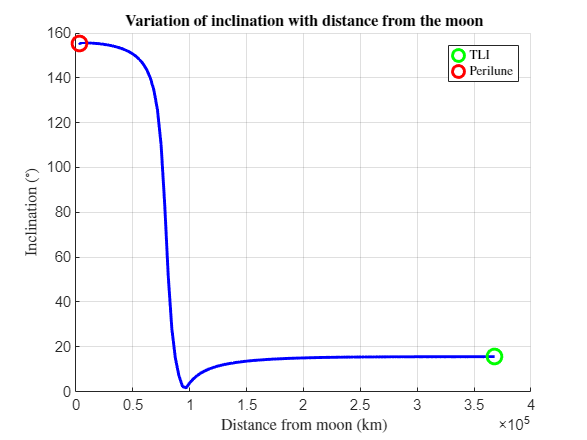

% Compute probe's relative speed to Moon at perilune
rel_speed = norm(v_atdmin - vm_perilune);
% Compute final point of trajectory
rend = [X(end); Y(end); Z(end)];
alt_end = norm(rend) - Re;
[ra_end, dec_end] = ra_and_dec_from_r(rend);

% Compute trajectory's osculating plane inclination
incl = zeros(imin, 1);
moon_distance = zeros(imin, 1);
for i = 1:imin
    r_vec = [X(i); Y(i); Z(i)];
    v_vec = [vX(i); vY(i); vZ(i)];
    rm_vec = [Xm(i); Ym(i); Zm(i)];

    a_earth = -mu_e * r_vec / norm(r_vec)^3;
    rms_vec = rm_vec - r_vec;
    a_moon = mu_m * (rms_vec / norm(rms_vec)^3 - rm_vec / norm(rm_vec)^3);

    atotal = a_earth + a_moon;
    binormal = cross(v_vec, atotal) / norm(cross(v_vec, atotal));

    incl(i) = acosd(binormal(3));
    moon_distance(i) = norm(r_vec - rm_vec);
end

% Plot: Inclination variation with Moon distance
figure;
hold on;
plot(moon_distance, incl, 'b', 'LineWidth', 2); 
plot(moon_distance(1), incl(1), 'go', 'MarkerSize', 10, 'LineWidth', 2); 
plot(moon_distance(imin), incl(imin), 'ro', 'MarkerSize', 10, 'LineWidth', 2); 
hold off;
xlabel('Distance from moon (km)', 'Interpreter', 'latex'); 
ylabel('Inclination ($^\circ$)', 'Interpreter', 'latex');
title('\bf{Variation of inclination with distance from the moon}', 'Interpreter', 'latex'); 
grid on;
legend('', 'TLI', 'Perilune', 'Interpreter', 'latex');


% Output: Probe conditions at Perilune
fprintf('\n=== Probe at Perilune ===\n');


=== Probe at Perilune ===


fprintf('Altitude above Moon             = %11.4f km\n', dist_min - Rm);

Altitude above Moon             =   1260.2450 km


fprintf('Absolute Speed                  = %11.4f km/s\n', norm(v_atdmin));

Absolute Speed                  =      1.0341 km/s


fprintf('Relative Speed to Moon          = %11.4f km/s\n', rel_speed);

Relative Speed to Moon          =      2.1102 km/s


fprintf('Inclination of Osculating Plane = %11.4f°\n', incl(imin));

Inclination of Osculating Plane =    155.3899°


fprintf('Time from TLI to Perilune       = %11.4f hours (%.4f days)\n', abs(t(imin))/3600, abs(t(imin))/(3600*24));

Time from TLI to Perilune       =     69.1248 hours (2.8802 days)


fprintf('Total Time of Flight            = %11.4f days\n', t(end)/days);

Total Time of Flight            =      5.6670 days


fprintf('Time to Target Point            = %11.4f days\n', ttt/days);

Time to Target Point            =      3.0000 days


fprintf('Final Earth Altitude            = %11.4f km\n', alt_end);

Final Earth Altitude            =   1271.2334 km


fprintf('Final RA                        = %11.4f°\n', ra_end);

Final RA                        =    261.4536°


fprintf('Final Dec                       = %11.4f°\n', dec_end);

Final Dec                       =    -27.1340°


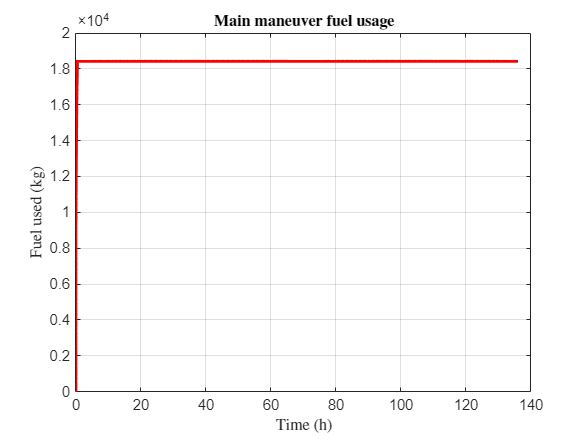

% Plot Fuel Consumption Profile
burn_duration = 1800; % Seconds
plot_fuel_vs_time(t, m0, delta_v, burn_duration, Isp);

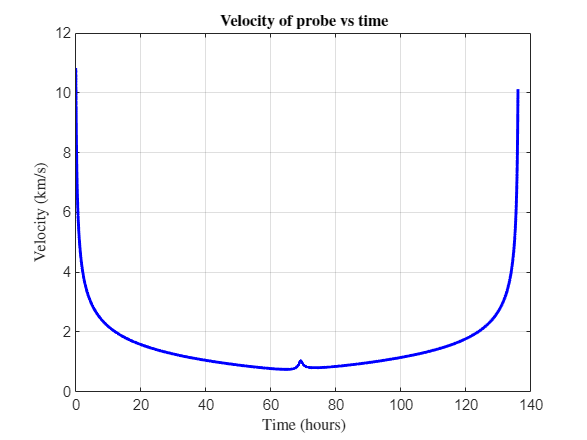


% Plot Probe Velocity over Time
v = sqrt(vX.^2 + vY.^2 + vZ.^2);
figure;
plot(t/3600, v, 'b', 'LineWidth', 2);
xlabel('Time (hours)', 'Interpreter', 'latex'); 
ylabel('Velocity (km/s)', 'Interpreter', 'latex');
title('\bf{Velocity of probe vs time}', 'Interpreter', 'latex'); 
grid on;

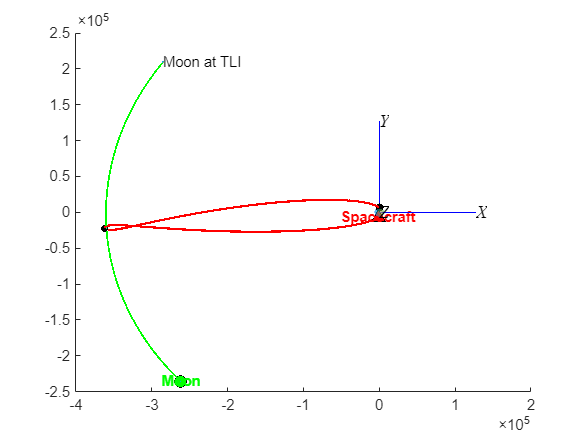

% Plot 3D Trajectories (with Animation)
plotit_XYZ(X, Y, Z, Xm, Ym, Zm, imin, Re, Rm);

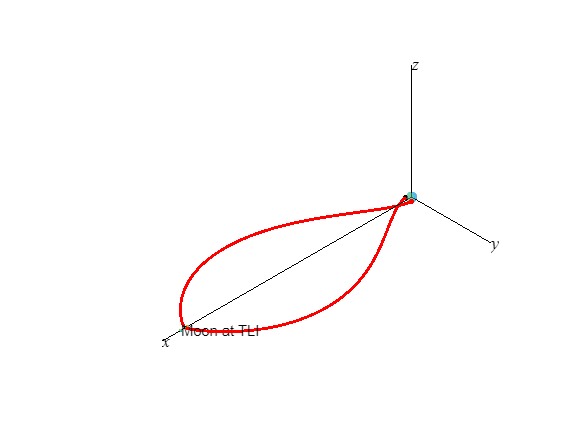

plotitxyz(x, y, z, xm, ym, zm, imin, Re, Rm);